# Notebook 02: Preprocessing and Feature Extraction

This research project contains 3 notebooks:

- Notebook 01: Project Overview

- Notebook 02: Preprocessing and Feature Extraction

- Notebook 03: ANN Training

You are currently running **Notebook 02**. Before running this notebook, you should have run Notebook 01 to get an understanding of the data you will be working with.

## Instructions

- Run each cell in order.

- Modify the lines that have green comments.

- This notebook, by default, assumes that time/samples are rows and channels are columns.

- Feel free to try more involved preprocessing steps, but assign your results back to the appropriate variables.

### Step 1: Ensure you are in the correct directory

clc;
clear;
cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Procedure 1: Preprocessing

### Step 1: Load the dataset

clearvars

pre_process_type = "train" % test or train

pre_process_type = "train"


switch pre_process_type
    case "test"
        load("datasets\testing_dataset.mat")
        training_data = testing_data;

    otherwise 
        load("datasets\training_dataset.mat")

end

### Step 2: Visualize the raw data

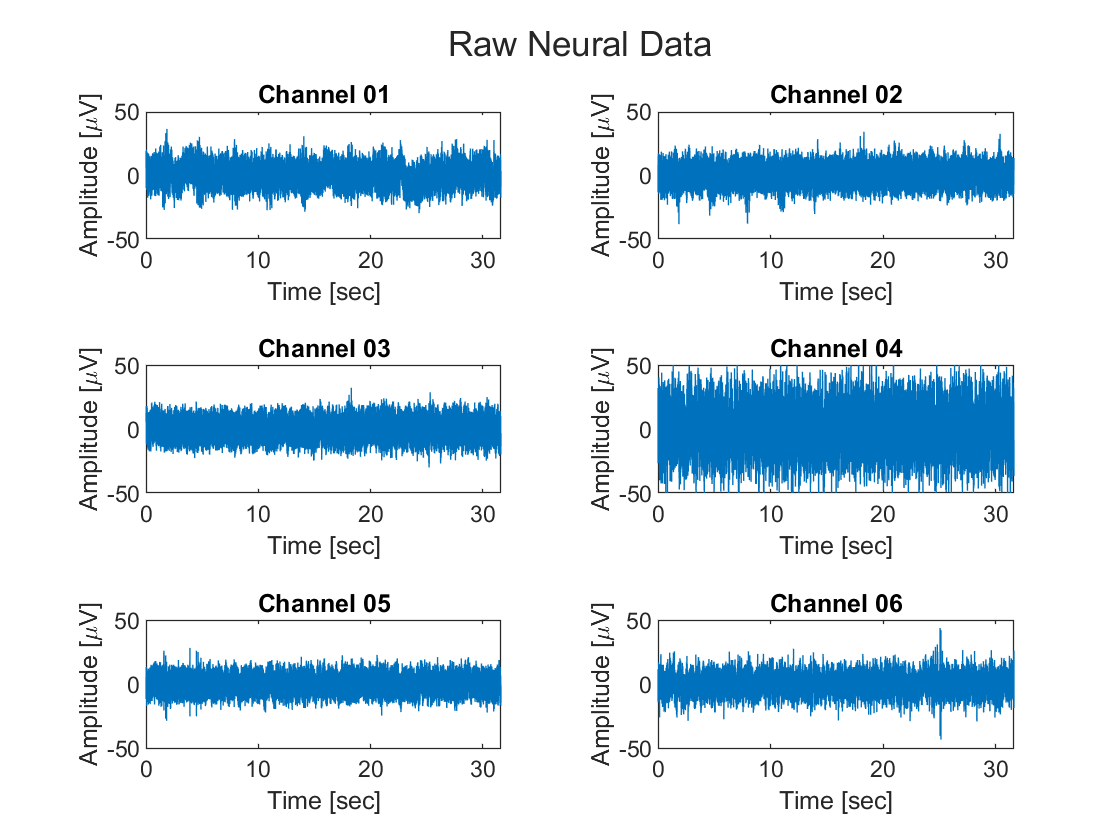

fig_1 = plot_raw_data(training_data);

### Step 3: Filter the data

#### A. Provide information for designing the filter

Assuming you want to use a high-pass filter to denoise the neural signals, answer the following questions:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% What is the sampling frequency of your signals in units of Hz?
sample_rate = 30000; % Change this random value to the actual value of the sample rate
% What cutoff frequency (in Hz) would you use for a highpass filter?
cut_off_freq = 750; % Change this random value
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

#### B. Design the filter and apply it to the signal

The function `butter` designs a filter using three arguments: filter order, normalized cut-off frequency, and filter type.

It returns the transfer function coefficients that match the provided specifications:


$$H(z) = \frac{B(z)}{A(z)} = \frac{b(1) + b(2)\,z^{-1} + b(n+1)\,z^{-n}}{a(1) + a(2)\,z^{-1} + a(n+1)\,z^{-n}}$$


filt_order = 4;
norm_cut_off = cut_off_freq / (sample_rate/2);
[b, a] = butter(filt_order, norm_cut_off, 'high'); % 4th order highpass filter

To apply the filter, we pass the transfer function to a precompiled method (`FilterX`) that has been optimized for speed. Alternatively, you can use MATLAB's [`filter()`](https://www.mathworks.com/help/matlab/ref/filter.html) function.

ch_init_conds = zeros(filt_order, 6); %initial conditions for filter for all channels
[filt_neural_data, ~] = FilterX(b, a, training_data.raw_neural_data, ch_init_conds);

%filt_neural_data = filt_neural_data - mean(filt_neural_data, 2);

#### Step 4: Visualize the filtered data

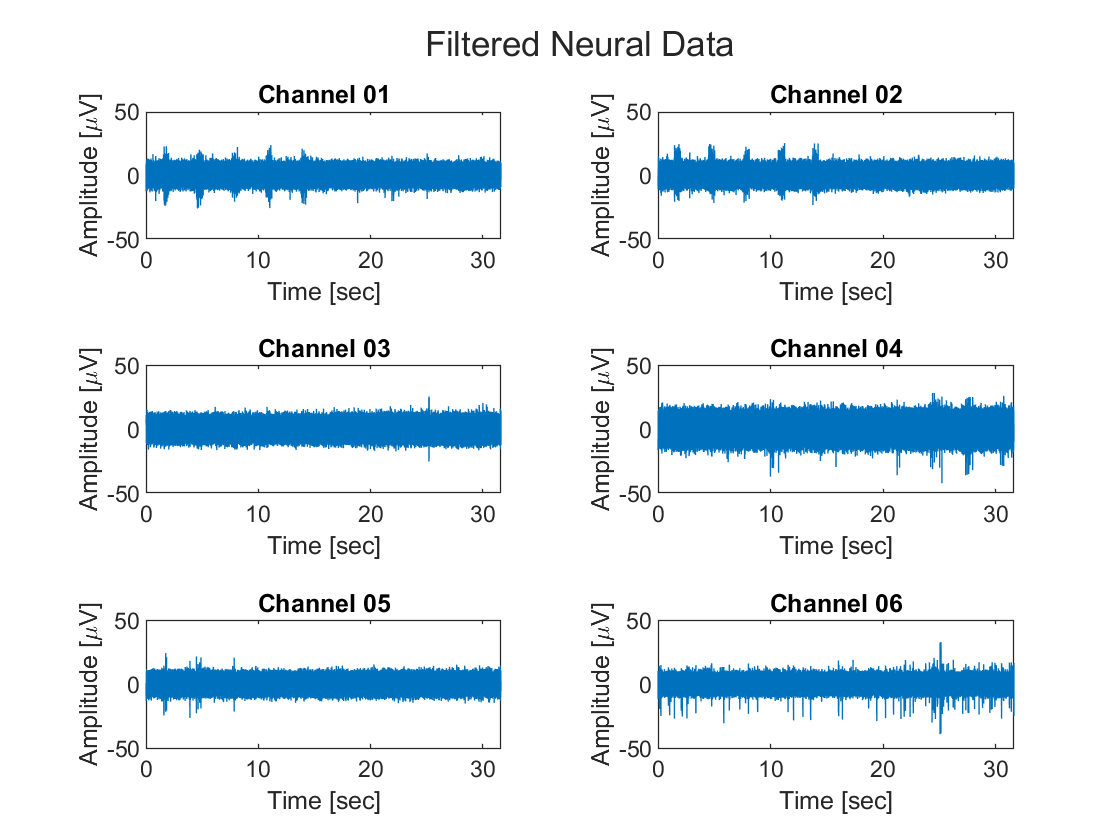

fig_2 = plot_filt_data(filt_neural_data, sample_rate);

## Procedure 2: Spike Detection

If your signal processing steps worked well, you should be able to detect some action action potentials.

### Step 1: Find the locations of the spikes (action potentials) for each channel

Your goal for this step is to provide the locations of spike occurrences in the `filt_neural_data` matrix.

You will start with the array `spike_locations`, which has the same shape as `filt_neural_data` and whose entries have been **initialized to zero**.

spike_locations = zeros(size(filt_neural_data))

spike_locations =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Then, modify the code below to replace `0`s with `1`s whenever you find a spike. We do this to leverage MATLAB's [logical indexing](https://blogs.mathworks.com/loren/2013/02/20/logical-indexing-multiple-conditions/) functionality down the line.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

thresh =  4.5*rms(filt_neural_data);
thresh(1,6) = thresh(1,6)+2;

% 2. Convert to double or single if stackedplot rejects logical arrays
spike_locations = filt_neural_data > thresh;

spike_locations = double(spike_locations);

filt_neural_data = double(filt_neural_data);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Step 2: Visualize the spike locations as spike trains in a raster plot

The raster plot below draws a vertical black line at each of the locations specified in `spike_locations`.

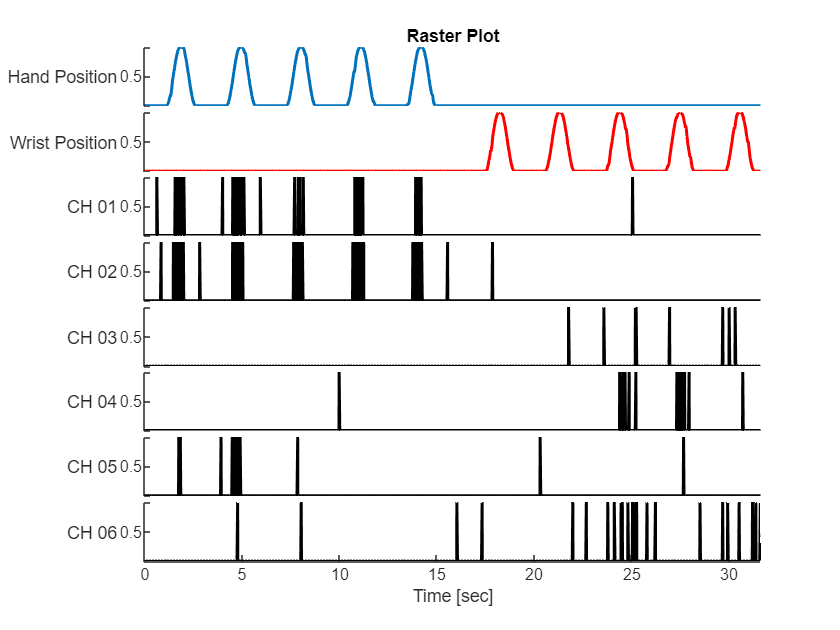

fig_3 = plot_spike_trains(spike_locations, training_data);

### Step 3: Plot the action potential waveforms using the spike locations

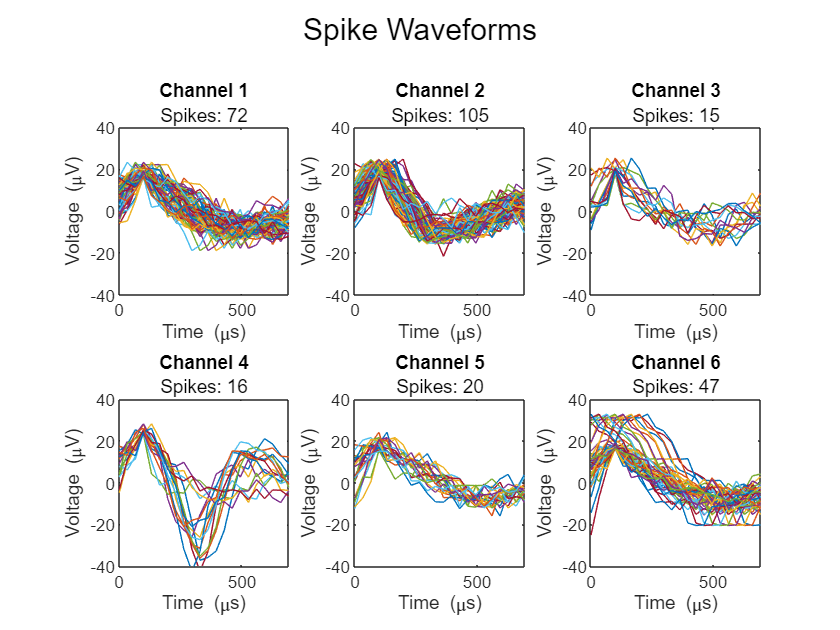

spike_waveforms = get_action_potentials(spike_locations, filt_neural_data, 'Spike Waveforms');

### Step 4: Calculate the SNR of each detected spike

First, let's explore how we have stored the waveforms associated with each spike. 

`spike_waveforms` is a [MATLAB cell array](https://www.mathworks.com/help/matlab/cell-arrays.html) that has one row per channel.

spike_waveforms

spike_waveforms = 6×1 cell array
    {1×72  cell}
    {1×105 cell}
    {1×15  cell}
    {1×16  cell}
    {1×20  cell}
    {1×47  cell}


Each of these rows is also a cell array containing a variable number of waveforms based on the information in `spike_locations`. 

spike_waveforms{:}

ans = 1×72 cell array
    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1

ans = 1×105 cell array
    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×

ans = 1×15 cell array
    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}


ans = 1×16 cell array
    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}


ans = 1×20 cell array
    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}


ans = 1×47 cell array
    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}    {22×1 double}


To access the waveforms, you need to specify the channel you want and the waveform you are interested in. 

chan_idx = 1; % random channel
waveform_idx = 3; % random waveform

The waveform itself is a vector containing `22` samples of neural data, which is equivalent to `0.1 ms` before and `0.6 ms `after the spike detection event.

waveform_data = spike_waveforms{chan_idx}{waveform_idx}

waveform_data =    10.8520
    5.0150
   12.2439
   15.5735
   16.7985
   22.1126
   22.2773
   14.9500
    5.2200
    6.2579


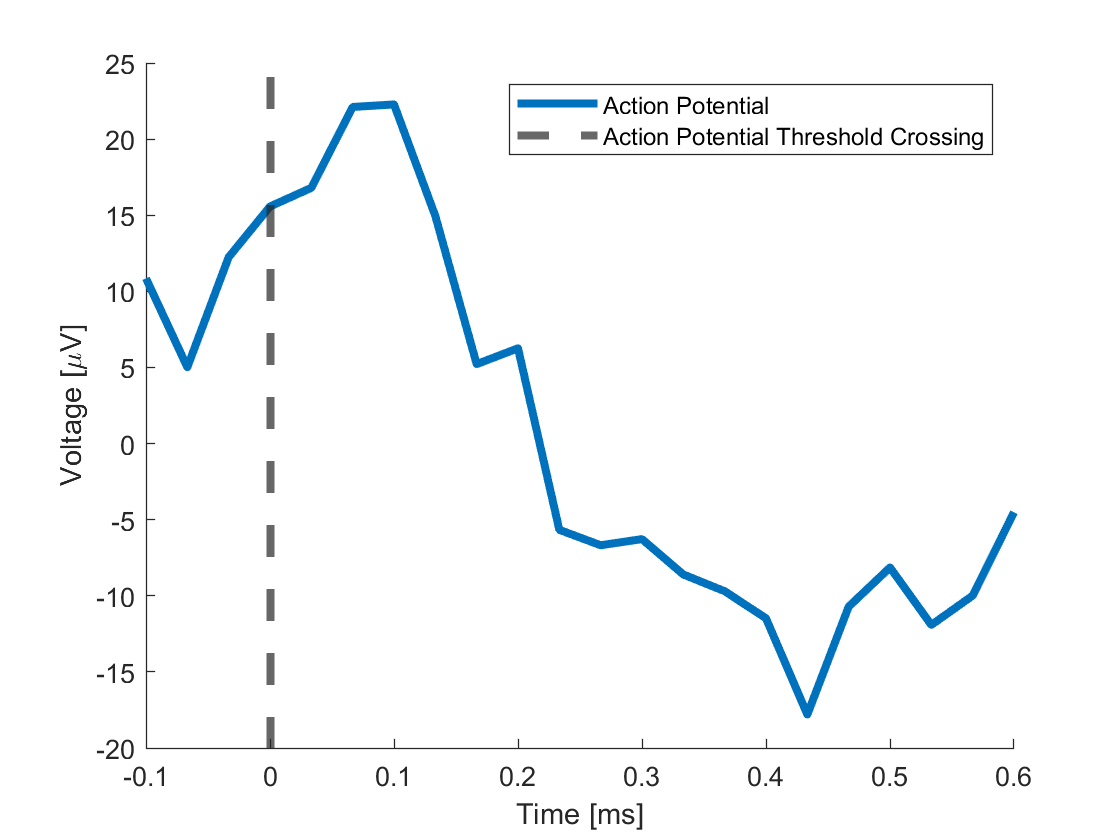

figure
waveform_time = (-3:1:18)'/training_data.sample_rate*1e3;
plot(waveform_time, waveform_data, LineWidth=3)
xline(0, LineWidth=3, LineStyle="--")
xlabel("Time [ms]")
ylabel("Voltage [\muV]")
legend(["Action Potential", "Action Potential Threshold Crossing"])
box off

Now, consider the image below, which shows action potentials as a function of distance to a neuron. Which action potential has the best SNR in the image below? Which channel of data provides the best SNR? Where might each channel be in relation to a given neuron? Are any channels recording from multiple neurons? 

One of your requirements for this research project is to determine if there are any statistical differences in the SNR among the electrodes.

For more context about the image below, read the document titled *"Introduction to Neural Recordings"* under the Neural Recordings Reading Assignment on Canvas. 

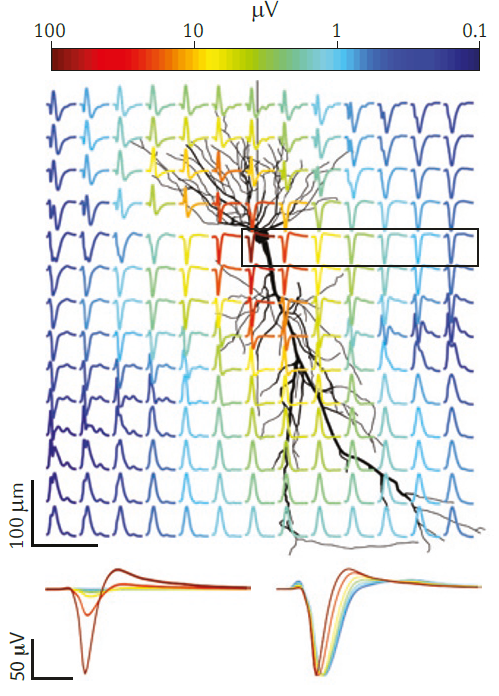

Calculate the SNR of each waveform in `spike_waveforms`. Use the following code to access each waveform:

snr_values = cell(1, 6);

for chan_idx = 1:6 % for each channel
    chan_waveforms = spike_waveforms{chan_idx};
    chan_snr = zeros(1, length(chan_waveforms));

    for waveform_idx = 1:length(chan_waveforms) % for each waveform in the channel
        waveform_data = chan_waveforms{waveform_idx};

        %%%%%%%%%%%%%%%%%%%%%%%% YOUR SNR CODE GOES HERE %%%%%%%%%%%%%%%%%%%
        % "Signal" = peak-to-peak amplitude of the spike waveform
        signal_amplitude = max(waveform_data) - min(waveform_data);

        % "Noise" = std of the pre-threshold-crossing baseline samples
        % (samples 1:3 correspond to the -3 to 0 index window, or before
        % the spike detection event)
        noise_std = std(waveform_data(1:3));

        % SNR definition
        % SNR = peak-to-peak signal / (2 * noise std)
        chan_snr(waveform_idx) = signal_amplitude / (2 * noise_std);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end

    snr_values{chan_idx} = chan_snr;
end

% --- Plot the SNR distributions ---
snrfig = figure();
boxplot_data = [];
boxplot_groups = [];
for chan_idx = 1:6
    boxplot_data = [boxplot_data, snr_values{chan_idx}];
    boxplot_groups = [boxplot_groups, chan_idx*ones(1, length(snr_values{chan_idx}))];
end
boxplot(boxplot_data, boxplot_groups)
xlabel('Channel')
ylabel('SNR')
title('SNR Distribution by Channel')
box off

% Run stats: is there a difference across channels?
[p, tbl, stats] = kruskalwallis(boxplot_data, boxplot_groups, 'off');
fprintf('Kruskal-Wallis p-value across channels: %.4g\n', p);

Kruskal-Wallis p-value across channels: 0.1249


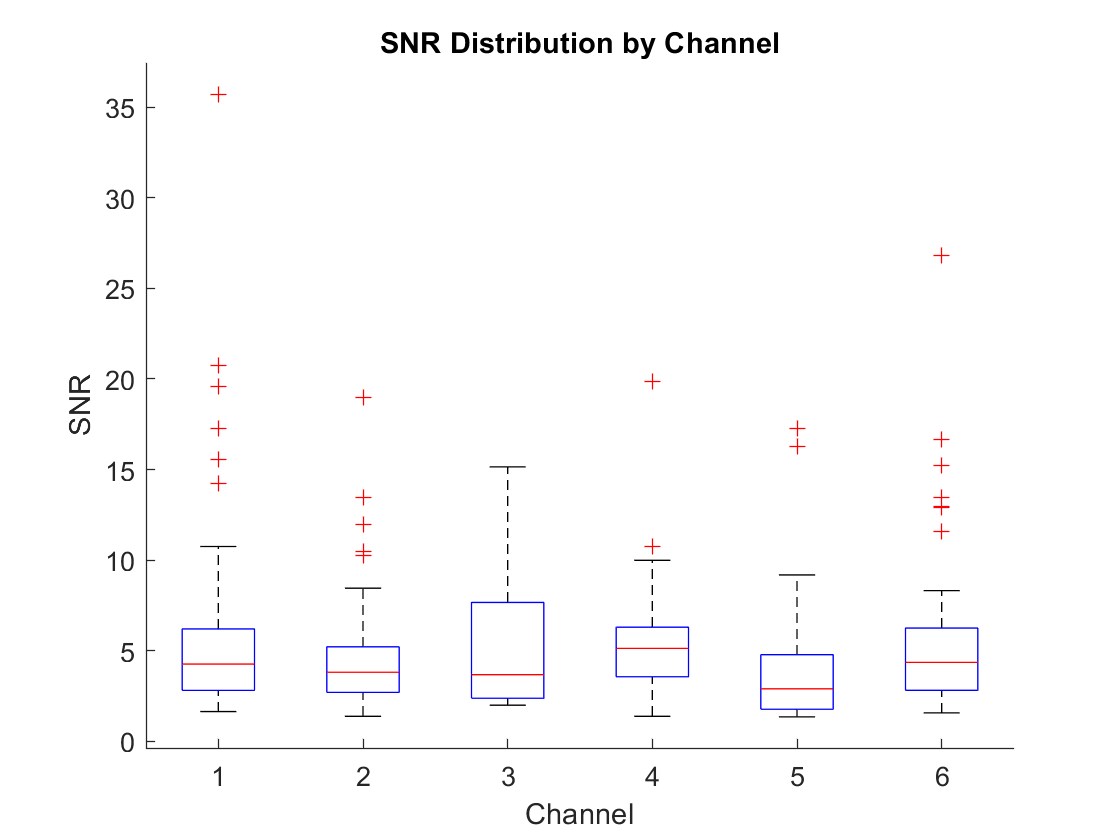


% If significant, follow up with pairwise comparisons
if p < 0.05
    figure
    multcompare(stats);
    title('Pairwise Channel Comparisons (SNR)')
end

exportgraphics(snrfig, 'images/fig3.png');

After you've calculated SNRs you should have 6 distributions total (1 for each channel). Make sure to **plot the SNR values** and **run stats**! 

## Procedure 3: Feature Extraction

### Step 1: Implement your feature extraction algorithm

The only requirement for generating features is that the length of your `neural_features` must match the size of the kinematics. The reason for this is that the kinematics are acting as labels for your features. For more information about this requirement, check notebook 03 on training the neural network.

If the lengths don't match as a result of your calculations, you can [pad the array with zeros](https://www.mathworks.com/help/images/ref/padarray.html).

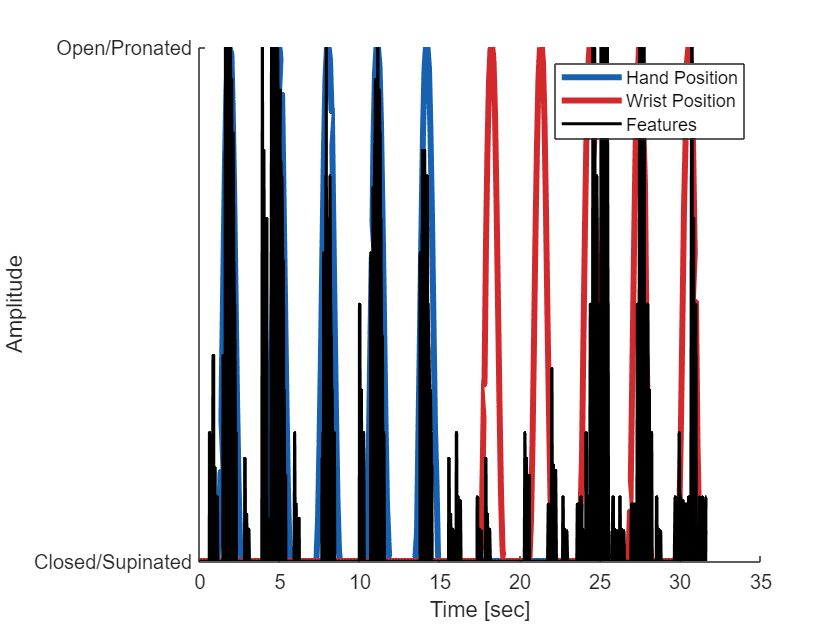

%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Feature extraction variable definitions
n_kinematic_samples = length(training_data.hand_kinematics);
n_neural_samples = size(spike_locations, 1);
n_chans = size(spike_locations, 2);
fs = training_data.sample_rate;


% (keeps one feature row per kinematic sample)

% Feature Extraction Method 1: Binning (multi-timescale firing rates)
% strong alone; also used inside combo.
bin_durations_sec = [0.05, 0.15, 0.30]; % 50, 150, 300 ms
neural_features_binned = zeros(n_kinematic_samples, n_chans * numel(bin_durations_sec));
spike_cs = [zeros(1, n_chans); cumsum(spike_locations, 1)];
for k = 1:numel(bin_durations_sec)
    bin_size = max(1, round(bin_durations_sec(k) * fs));
    col0 = (k - 1) * n_chans;
    for bin_idx = 1:n_kinematic_samples
        idx_end = bin_idx;
        idx_start = max(1, idx_end - bin_size + 1);
        neural_features_binned(bin_idx, col0 + (1:n_chans)) = ...
            (spike_cs(idx_end + 1, :) - spike_cs(idx_start, :)) / bin_size;
    end
end
assert(length(neural_features_binned) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
plot_features(training_data, normalize(neural_features_binned, "range", [0 1]));

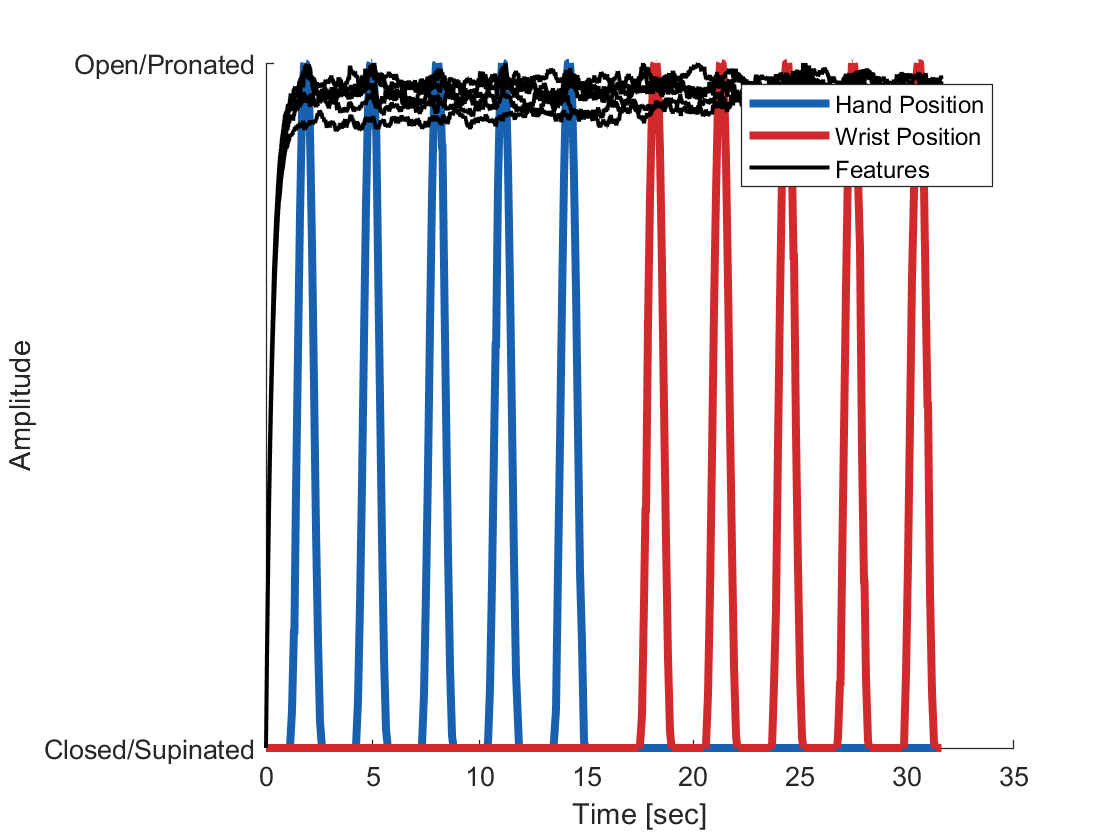



% feature Extraction Method 2: Simple Exponential Smoothing (SES)

tau_sec = 0.30;
alpha = 1 - exp(-1 / (tau_sec * fs));
neural_features_SES = filter(alpha, [1, -(1 - alpha)], abs(filt_neural_data));
assert(length(neural_features_SES) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")

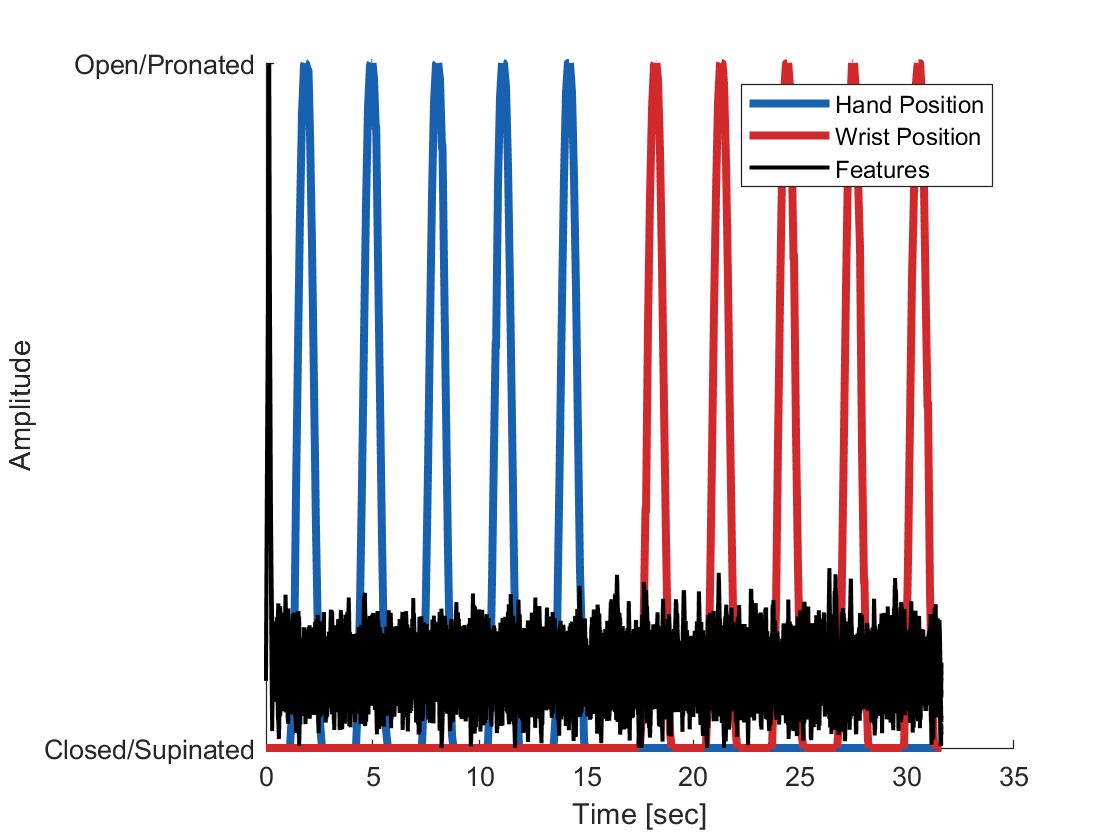

plot_features(training_data, normalize(neural_features_SES, "range", [0 1]));


% Feature Extraction Method 3/4: Zero crossings (weak rn)
win_size = max(1, round(0.15 * fs));
sig = zeros(n_neural_samples, n_chans);
neural_features_ZC = zeros(n_neural_samples, n_chans);
neural_features_ZCR = zeros(n_neural_samples, n_chans);
sigsum = zeros(n_neural_samples, n_chans);
trans = zeros(n_neural_samples, n_chans);
meansigsum = zeros(n_neural_samples, n_chans);
sig(1,:) = filt_neural_data(1,:) >= 0;
for j = 1:n_chans
    for i = 2:n_neural_samples
        sig(i,j) = double(filt_neural_data(i,j) >= 0);
        trans(i,j) = abs(sig(i,j) - sig(i-1,j));
        if i > win_size
            sigsum(i,j) = sigsum(i-1,j) + trans(i,j) - trans(i-win_size,j);
            meansigsum(i,j) = meansigsum(i-1,j) + (sigsum(i,j) - sigsum(i-win_size,j))/win_size;
            win_size_len = win_size;
        else
            win_size_len = max(1, i-1);
            sigsum(i,j) = sigsum(i-1,j) + trans(i,j) - trans(i-win_size_len,j);
            meansigsum(i,j) = mean(sigsum(1:i,j));
        end
        neural_features_ZC(i,j) = sigsum(i,j) - meansigsum(i,j);
        neural_features_ZCR(i,j) = neural_features_ZC(i,j) / win_size_len;
    end
end
assert(length(neural_features_ZC) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
assert(length(neural_features_ZCR) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")

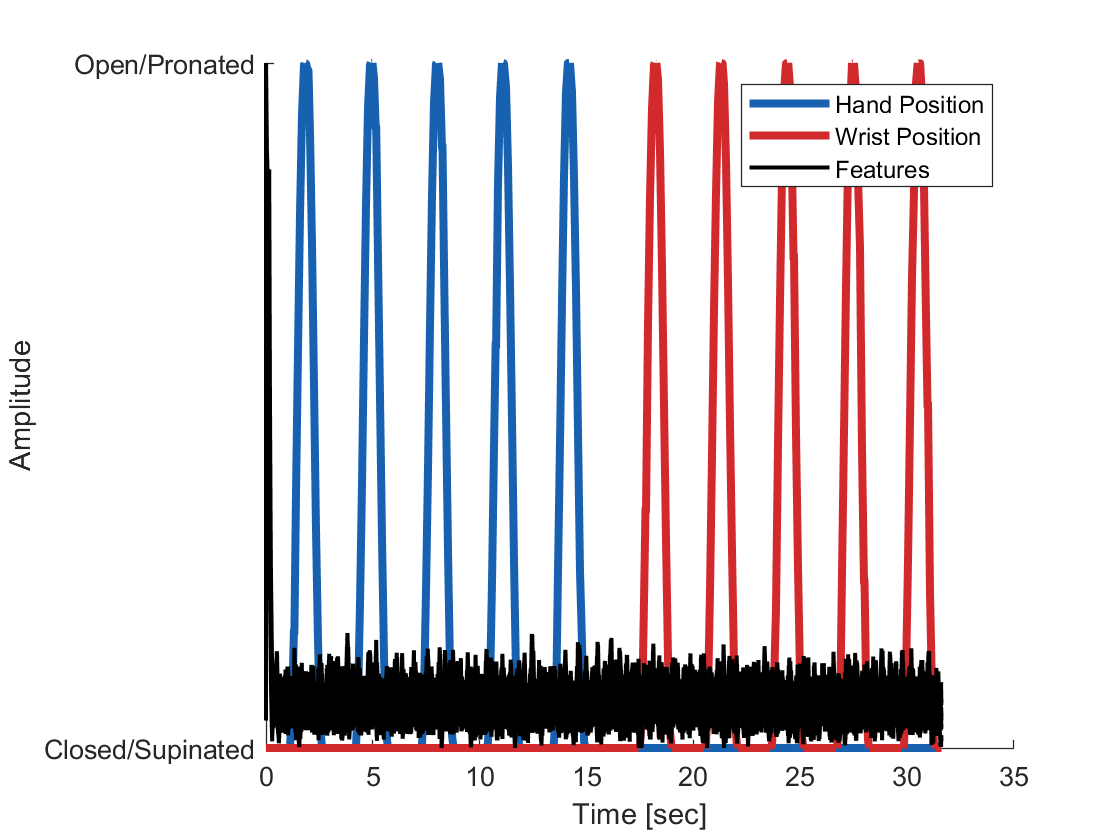

plot_features(training_data, normalize(neural_features_ZC, "range", [0 1]));

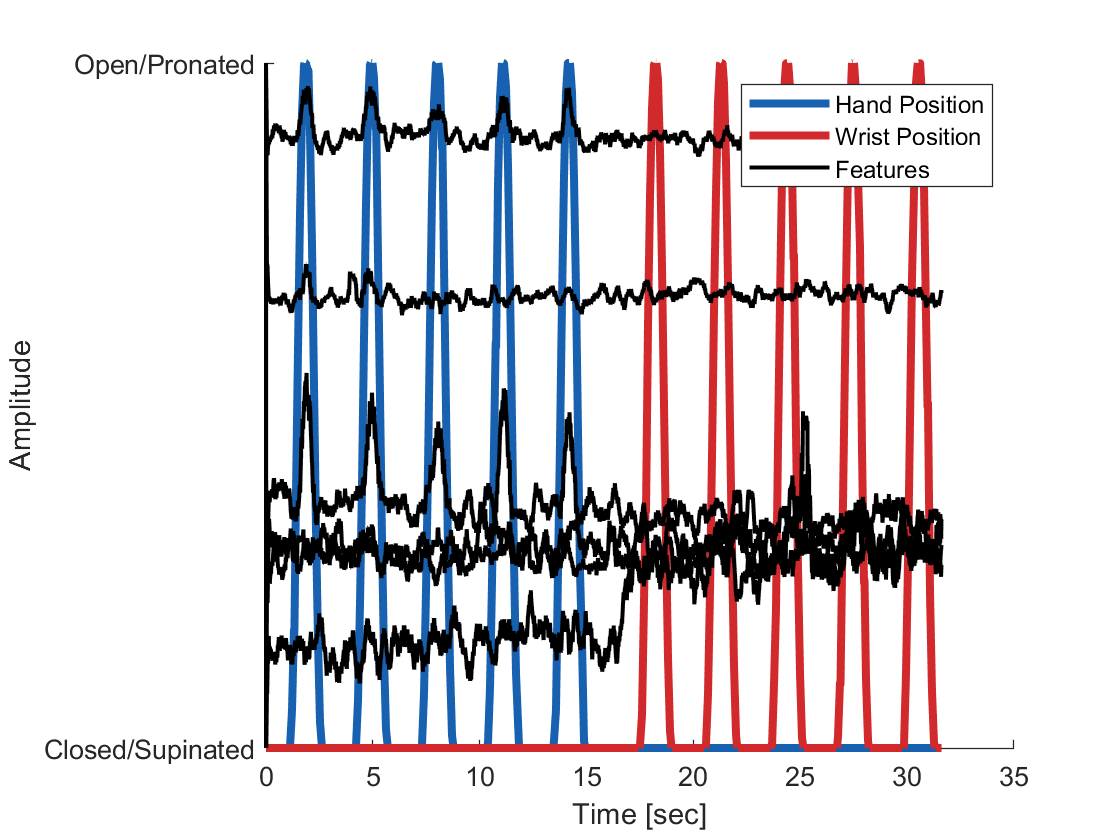

plot_features(training_data, normalize(neural_features_ZCR, "range", [0 1]));


% Feature Extraction Method 5: Sliding RMS (300 ms)
rms_win_size = max(1, round(0.30 * fs));
sq = filt_neural_data.^2;
sumsq = [zeros(1, n_chans); cumsum(sq, 1)];
neural_features_RMS = zeros(n_neural_samples, n_chans);
for i = 1:n_neural_samples
    idx_start = max(1, i - rms_win_size + 1);
    win_len = i - idx_start + 1;
    neural_features_RMS(i,:) = sqrt((sumsq(i + 1,:) - sumsq(idx_start,:)) / win_len);
end
assert(length(neural_features_RMS) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")

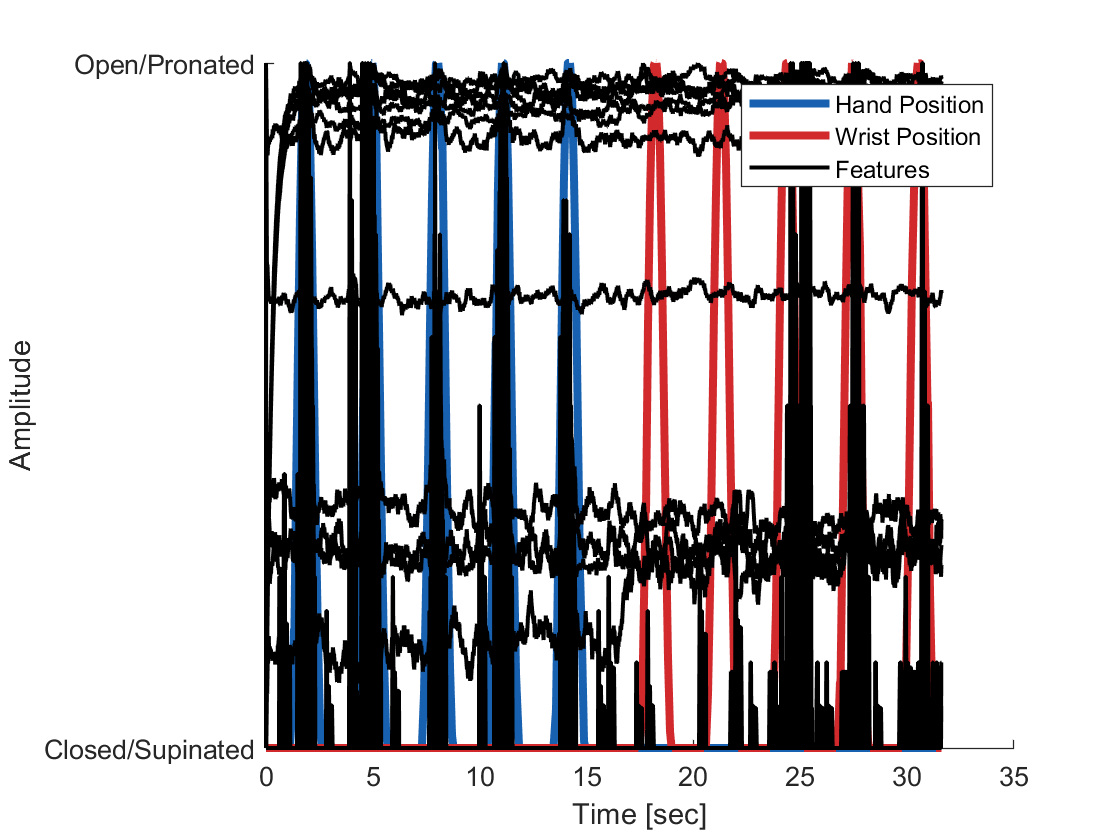

plot_features(training_data, normalize(neural_features_RMS, "range", [0 1]));


% feature Extraction Method 6: COMBO
% Concatenate binned + RMS + SES
neural_features_combo = [neural_features_binned, neural_features_RMS, neural_features_SES];
assert(length(neural_features_combo) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")

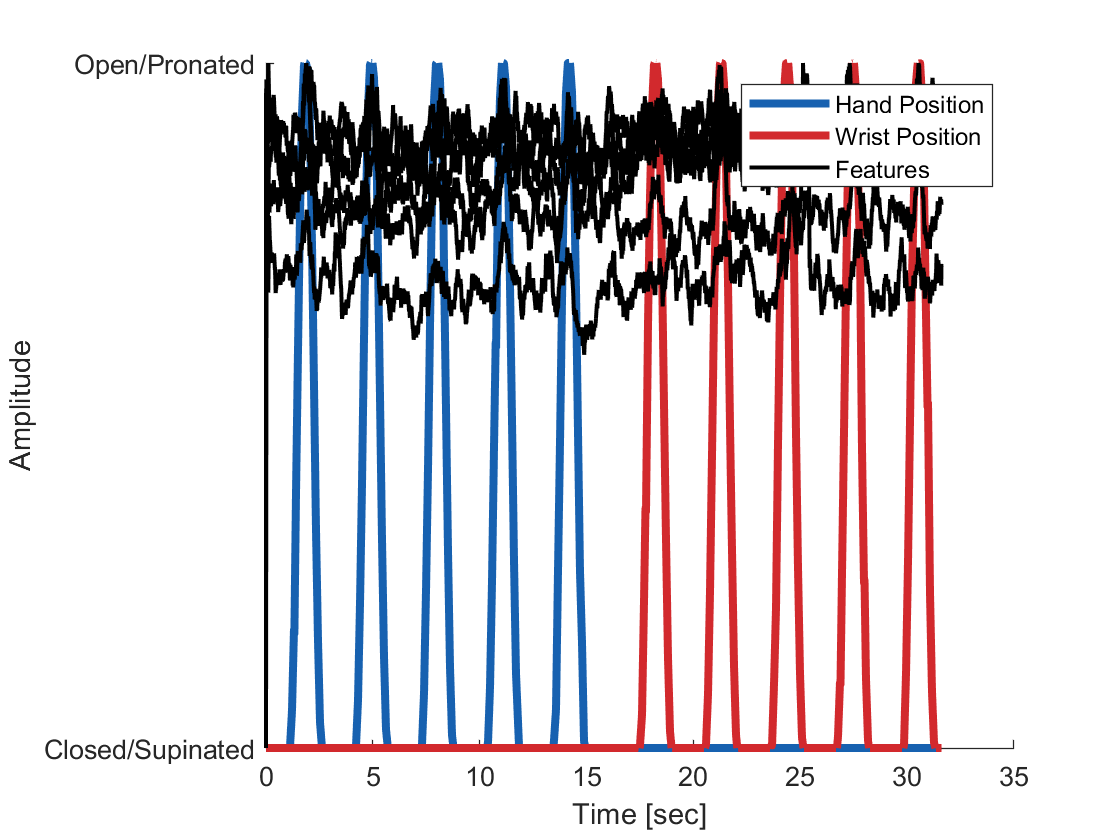

plot_features(training_data, normalize(neural_features_combo, "range", [0 1]));


% % Feature Extraction Method 7: spike-band power (SBP) rms
fs = 30000;                 % neural sampling rate (Hz)

% 300–1000 Hz spike-band filter
[b, a] = butter(2, [300 1000]/(fs/2), 'bandpass');

% Causal filtering: matches a real-time implementation.
% Filter along dimension 1 (time).
x_300_1000Hz = filter(b, a,training_data.raw_neural_data);


sq_BP = x_300_1000Hz.^2;
sumsq_SBPrms= [zeros(1, n_chans); cumsum(sq_BP, 1)];
neural_features_SBP_rms = zeros(n_neural_samples, n_chans);
for i = 1:n_neural_samples
    idx_start = max(1, i - rms_win_size + 1);
    win_len = i - idx_start + 1;
    neural_features_SBP_rms(i,:) = sqrt((sumsq_SBPrms(i + 1,:) - sumsq_SBPrms(idx_start,:)) / win_len);
end
assert(length(neural_features_SBP_rms) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")

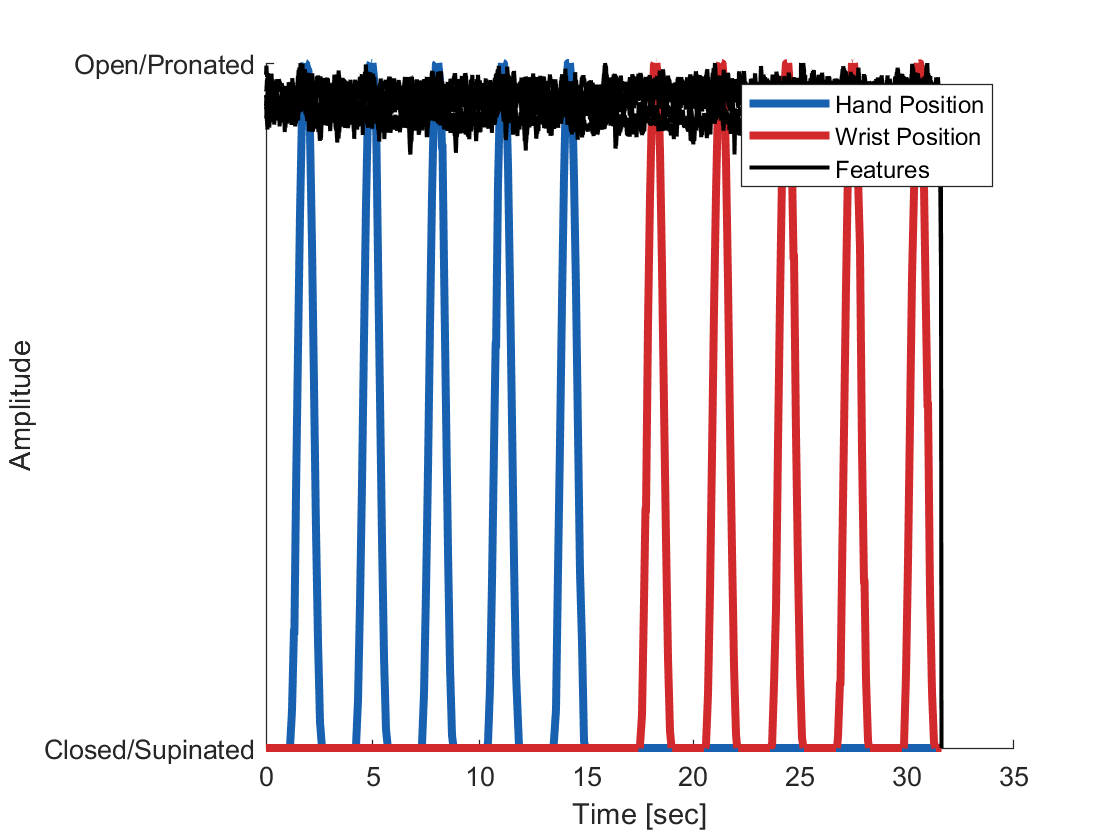

plot_features(training_data, normalize(neural_features_SBP_rms, "range", [0 1]));
% 


% Feature Extraction Method: spike band power (SBP) power
windowMs = 100; %ms
windowSamples = round(windowMs/1000 * fs);
x_300_1000Hz_pad = [x_300_1000Hz; zeros(windowSamples, n_chans)];

SBP = zeros(n_neural_samples, n_chans);

for i = 1:n_neural_samples
    idx = i : ...
         i + windowSamples - 1;
    windowData = x_300_1000Hz_pad(idx, :);

    % Mean squared voltage in the spike band, per channel
    SBP(i, :) = mean(windowData.^2, 1);
end

% Usually preferable for regression/ANN input
neural_features_logSBP = log(SBP + eps);
assert(length(neural_features_logSBP) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")

plot_features(training_data, normalize(neural_features_logSBP, "range", [0 1]));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Save UNNORMALIZED features. Notebook 03 fits range-norm on TRAIN and
% applies the same min/max to TEST (critical for generalization).
switch pre_process_type
    case "test"
        % applies the same min/max to TEST (critical for generalization).
        save("results\features_binned_test", "neural_features_binned");
        save("results\features_SES_test", "neural_features_SES");
        save("results\features_ZC_test", "neural_features_ZC");
        save("results\features_ZCR_test", "neural_features_ZCR");
        save("results\features_RMS_test", "neural_features_RMS");
        save("results\features_combo_test", "neural_features_combo");
        save("results\features_bpRMS_test", "neural_features_SBP_rms");
        save("results\features_logSBP_test", "neural_features_logSBP");

    otherwise
        save("results\features_binned", "neural_features_binned");
        save("results\features_SES", "neural_features_SES");
        save("results\features_ZC", "neural_features_ZC");
        save("results\features_ZCR", "neural_features_ZCR");
        save("results\features_RMS", "neural_features_RMS");
        save("results\features_combo", "neural_features_combo");
        save("results\features_bpRMS", "neural_features_SBP_rms");
        save("results\features_logSBP", "neural_features_logSBP");

end




dsf

% % Sample EEG data
% fs = 256;
% eegData = filt_neural_data; % Example EEG data
% % plot the EEG signal
% figure;
% subplot(6,1,1);
% p=plot(eegData);
% title('EEG Signal')
% % wavelet decomposition
% waveletFunction = 'db8';
% [C,L] = wavedec(eegData(:,1),8,waveletFunction);
% % extracting the details and approximation coefficients
% cD1 = detcoef(C,L,1);
% cD2 = detcoef(C,L,2);
% cD3 = detcoef(C,L,3);
% cD4 = detcoef(C,L,4);
% cD5 = detcoef(C,L,5); %GAMMA
% cD6 = detcoef(C,L,6); %BETA
% cD7 = detcoef(C,L,7); %ALPHA
% cD8 = detcoef(C,L,8); %THETA
% cA8 = appcoef(C,L,waveletFunction,8); %DELTA
% % Reconstructing the Signal components
% D1 = wrcoef('d',C,L,waveletFunction,1);
% D2 = wrcoef('d',C,L,waveletFunction,2);
% D3 = wrcoef('d',C,L,waveletFunction,3);
% D4 = wrcoef('d',C,L,waveletFunction,4);
% D5 = wrcoef('d',C,L,waveletFunction,5); %GAMMA
% D6 = wrcoef('d',C,L,waveletFunction,6); %BETA
% D7 = wrcoef('d',C,L,waveletFunction,7); %ALPHA
% D8 = wrcoef('d',C,L,waveletFunction,8); %THETA
% A8 = wrcoef('a',C,L,waveletFunction,8); %DELTA
% % plotting the frequency bands
% Gamma = D5;
% subplot(6,1,2); 
% plot(1:1:length(Gamma),Gamma);title('GAMMA');
% Beta = D6;
% subplot(6,1,3); 
% plot(1:1:length(Beta), Beta); title('BETA');
% Alpha = D7;
% subplot(6,1,4); 
% plot(1:1:length(Alpha),Alpha); title('ALPHA');
% Theta = D8;
% subplot(6,1,5); 
% plot(1:1:length(Theta),Theta);title('THETA');
% D8 = detrend(D8,0);
% Delta = A8;
% subplot(6,1,6);
% plot(1:1:length(Delta),Delta);title('DELTA');

## Plot Figure 2


%Three part figure. From one example channel, show: A) unfiltered neural data, B) filtered neural data, C) example neural unit waveforms. Include timescales for each!
ex_channel_fig = figure();

chan_idx = 1; % channel
waveform_idx = 3; % waveform
spike_locs = find(spike_locations == 1);

t = (0:1:length(training_data.hand_kinematics)-1)/training_data.sample_rate;


fig_raw = tiledlayout(3,1);

ax_handles{1} = nexttile;
hold on;
plot(t,training_data.raw_neural_data(:,chan_idx))
xline(t(spike_locs( waveform_idx,chan_idx)), LineWidth=3, LineStyle="--")
ax_handles{2} = nexttile;
hold on;
plot(t,filt_neural_data(:,chan_idx))
xline(t(spike_locs( waveform_idx,chan_idx)), LineWidth=3, LineStyle="--")
ax_handles{3} = nexttile;
hold on;

waveform_data = spike_waveforms{chan_idx}{waveform_idx}

waveform_data =    10.8520
    5.0150
   12.2439
   15.5735
   16.7985
   22.1126
   22.2773
   14.9500
    5.2200
    6.2579


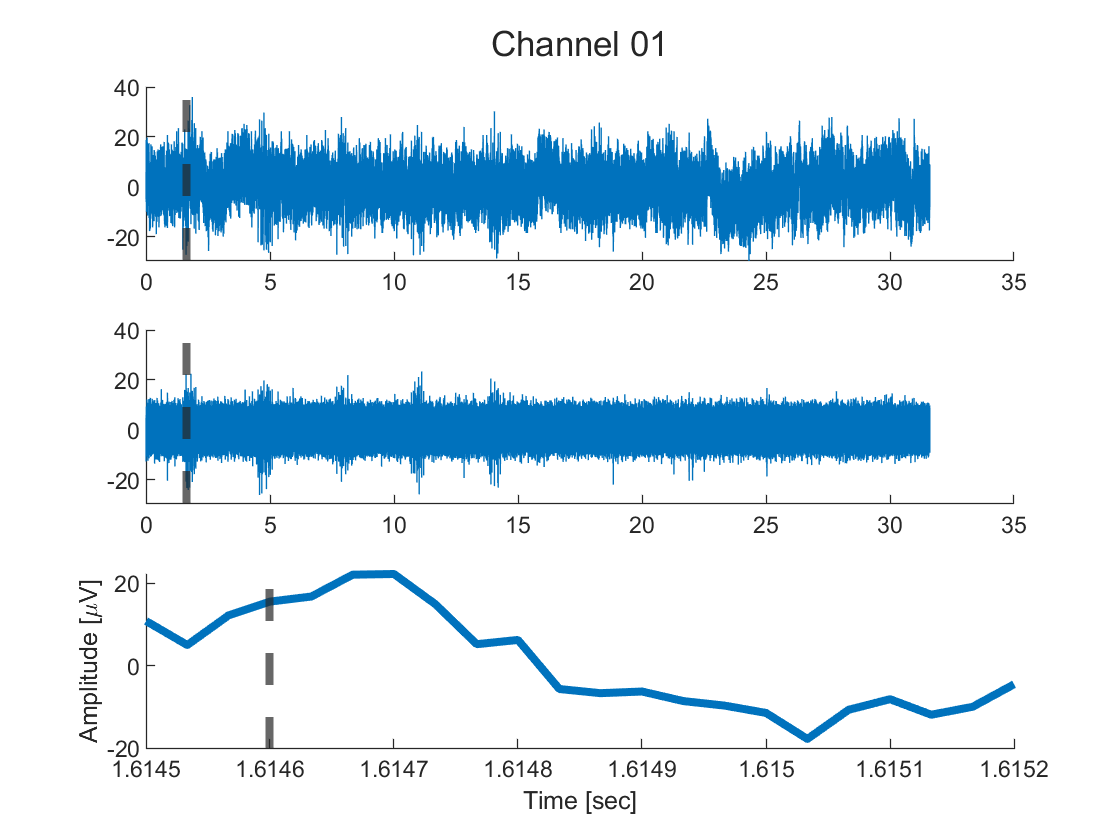


neg_offset = -3;
pos_offset = 18;



idx_start = spike_locs( waveform_idx,chan_idx) + neg_offset;
idx_end =  spike_locs( waveform_idx,chan_idx) + pos_offset;


waveform_time = t(idx_start:idx_end); %(-3:1:18)'/training_data.sample_rate*1e3;
plot(waveform_time, waveform_data, LineWidth=3)
xline(t(spike_locs( waveform_idx,chan_idx)), LineWidth=3, LineStyle="--")
% xlabel("Time [ms]")
% ylabel("Voltage [\muV]")
% legend(["Action Potential", "Action Potential Threshold Crossing"])
% box off

xlabel('Time [sec]')
ylabel('Amplitude [\muV]')



linkaxes([ax_handles{1:2}], 'xy');


title(fig_raw, sprintf('Channel %02d', chan_idx))

exportgraphics(ex_channel_fig, 'images/fig2.png');

## Helper Functions

This section contains the functions used for data visualization throughout this notebook. You do not need to change or understand the code below, but you are welcome to do so if it helps with your project.

function fig_handle = plot_raw_data(training_data)
[num_samples, num_chans] = size(training_data.raw_neural_data);
timestamps = (1:num_samples)/training_data.sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, training_data.raw_neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Raw Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_filt_data(neural_data, sample_rate)
[num_samples, num_chans] = size(neural_data);
timestamps = (1:num_samples)/sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Filtered Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_spike_trains(spike_locations, training_data)
fig_handle = figure;
t = (0:1:length(spike_locations)-1)'/training_data.sample_rate;
raster_handle = stackedplot(t, [training_data.hand_kinematics, spike_locations], LineWidth=1.5);
raster_handle.Color = "black";
raster_handle.LineProperties(1).Color = "#0072BD";
raster_handle.LineProperties(2).Color = "red";
raster_handle.DisplayLabels = ["Hand Position", "Wrist Position", "CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06"];
raster_handle.XLabel = "Time [sec]";
raster_handle.Title = "Raster Plot";
end


function spike_waveform_container = get_action_potentials(spike_trains, neural_data, plot_title)
[~, n_chans] = size(neural_data);
figure()
sgtitle(plot_title)
spike_waveform_container = cell(n_chans,1);
for chan=1:n_chans
    neg_offset = -3;
    pos_offset = 18;
    spike_locations = spike_trains(:,chan);
    spike_locations = find(spike_locations == 1);
    spike_count = sum(spike_trains);
    spikes = cell(1, spike_count(chan));

    subplot(2, 3, chan)
    for spike_idx = 1:length(spikes)
        idx_start = spike_locations(spike_idx) + neg_offset;
        idx_end = spike_locations(spike_idx) + pos_offset;
        try
            spikes{spike_idx} = neural_data(idx_start:idx_end, chan);
            plot(0:33:700, spikes{spike_idx});
        catch
        end
        hold on;
        spike_waveform_container{chan} = spikes;
    end
    xlabel('Time (\mus)')
    ylabel('Voltage (\muV)')
    hold off
    title(['Channel ' num2str(chan)])
    subtitle(['Spikes: ' num2str(length(spikes))])
    ylim([-40, 40])
end
end

function fig_handle = plot_features(training_data, neural_features)
fig_handle = figure;
hold on
t = (0:1:length(training_data.hand_kinematics)-1)/training_data.sample_rate;
plot(t, training_data.hand_kinematics(:,1), 'LineStyle','-','Color', "#1761B0", 'LineWidth', 3)
plot(t, training_data.hand_kinematics(:,2), 'LineStyle','-','Color', "#D2292D", 'LineWidth', 3)
plot(t, neural_features,'Color',"#000000" ,'LineWidth', 1.5)
hold off
box off
ylim([0 1])
yticks([0 1])
yticklabels({"Closed/Supinated", "Open/Pronated"})
xlabel("Time [sec]")
ylabel("Amplitude")
legend(["Hand Position", "Wrist Position", "Features"])
end